#  ENME462 Studio 6 Steady-State Error

by Xie Zheng

Section 0101 W 1:00PM - 2:50PM; Section 0103 F 10:00AM - 11:50AM

Github: [https://github.com/XieGT/Control_Studios](https://github.com/XieGT/Control_Studios)

**Steady-state error** is the difference between the **input** and **output** for a prescribed test input as $t\rightarrow\infty$

$e_{ss}$in terms of forward transfer function G(s) in unity feedback systems

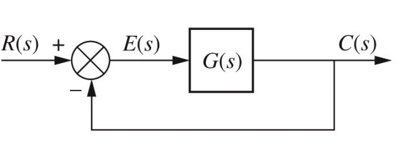


$$ T(s)=\frac{G(s)}{1+G(s)\cdot1}$$



$$T_e=\frac{E(s)}{R(s)}=\frac{R(s)-C(s)}{R(s)}=1-T(s)=\frac{1}{1+G(s)}$$



$$E(s)=T_e(s)\cdot R(s)=\frac{1}{1+G(s)}\cdot R(s)$$



$$e_{ss}=e(t\rightarrow\infty)=\lim_{s\rightarrow0}sE(s)=\lim_{s\rightarrow0}sT_e(s)R(s)=\lim_{s\rightarrow0}\frac{sR(s)}{1+G(s)}$$


## **Different Input Signals r(t)**

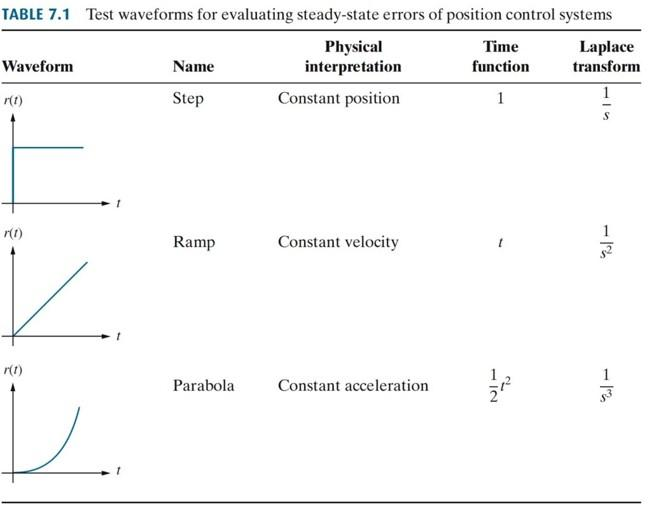

***Step input:  ***


$$e_{ss}=e_{step}(\infty)=\lim_{s\rightarrow0}\frac{s(1/s)}{1+G(s)}=\frac{1}{1+\lim_{s\rightarrow0}G(s)}=\frac{1}{1+K_p}$$
 

position constant: $K_p=\lim_{s\rightarrow0}G(s)$

***Ramp input:***


$$e_{ss}=e_{step}(\infty)=\lim_{s\rightarrow0}\frac{s(1/s^2)}{1+G(s)}=\lim_{s\rightarrow0}\frac{1}{s+sG(s)}=\frac{1}{\lim_{s\rightarrow0}sG(s)}=\frac{1}{K_v}$$


velocity constant: $K_v=\lim_{s\rightarrow0}sG(s)$

***Parabola input:***


$$e_{ss}=e_{step}(\infty)=\lim_{s\rightarrow0}\frac{s(1/s^3)}{1+G(s)}=\lim_{s\rightarrow0}\frac{1}{s^2+s^2G(s)}=\frac{1}{\lim_{s\rightarrow0}s^2G(s)}=\frac{1}{K_a}$$


acceleration constant: $K_a=\lim_{s\rightarrow0}s^2G(s)$

## System Type Number


$$G(s)=\frac{q(s)}{s^Np(s)}=\frac{(s+z_1)(s+z_2)...}{s^N(s+p_1)(s+p_2)...}$$


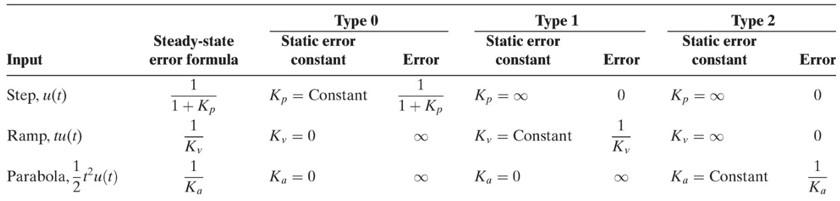

**Example 1.** A space station shown below in (a) will keep its solar arrays facing the sun using a solar tracking control system. The simplified block diagram in (b) represents the solar tracking control system that is used to rotatethe solar arrays. 

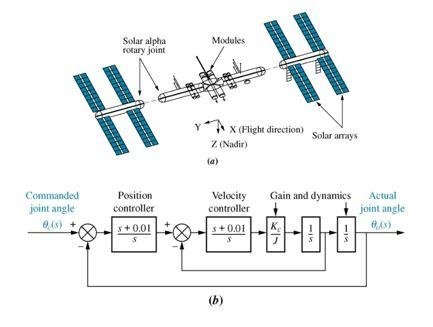

A) What is the steady-state error for step commands? Why?

B) What is the steady-state error for ramp commands? Why?

C) What is the steady-state error for parabolic commands? Why?

For the inner loop

$G_i(s)=\frac{K(s+0.01)/s^2}{1+K(s+0.01)/s^2}=\frac{K(s+0.01)}{s^2+Ks+0.01K}$ , where $K=\frac{K_c}{J}$

The inner closed loop transfer function 


$$G(s)=\frac{s+0.01}{s}\cdot G_i(s)\cdot \frac{1}{s}=K\frac{(s+0.01)^2}{s^2(s^2+Ks+0.01K)}$$


System is Type 2.


$$K_p=\lim_{s\rightarrow0}G(s)=\infty \qquad\rightarrow \qquad e_{step}(\infty)=\frac{1}{1+K_p}=\frac{1}{1+\infty}=0\\
K_v=\lim_{s\rightarrow0}sG(s)=\infty \qquad \rightarrow \qquad e_{ramp}(\infty)=\frac{1}{K_v}=\frac{1}{\infty}=0\\
K_a=\lim_{s\rightarrow0}s^2G(s)=0.01 \quad \rightarrow \quad e_{parabola}(\infty)=\frac{1}{K_a}=\frac{1}{0.01}=100$$
          

%% 1: MALTAB symbolic calculation
syms s K                      % define s, K are symbolic variables 
assume(K,'positive')          % assume K is a postive number 
num = (s+0.01)^2;
den = s^2 * (s^2 + K*s + 0.01*K);
G = K * num/den;
T_e = 1/(1+G);
T_e = simplify(T_e);
T_e = collect(T_e)

$$T\_e = \frac{10000\,s^{4}+\left(10000\,K\right)\,s^{3}+\left(100\,K\right)\,s^{2}}{10000\,s^{4}+\left(10000\,K\right)\,s^{3}+\left(10100\,K\right)\,s^{2}+\left(200\,K\right)\,s+K}$$


% 1.1 final value therom
R_step = 1/s;
ess_step = limit(s * T_e * R_step, s, 0)

$$ess\_step = 0$$


R_ramp = 1/(s^2);
ess_ramp = limit(s * T_e * R_ramp, s, 0)

$$ess\_ramp = 0$$


R_parabola = 1/(s^3);
ess_parabola = limit(s * T_e * R_parabola, s, 0)

$$ess\_parabola = 100$$


% 1.2 error constant 

Kp = limit(G,s,0)

$$Kp = \infty$$

ess_step = 1/(1+Kp)

$$ess\_step = 0$$


Kv = limit(s*G,s,0)

$$Kv = \mathrm{NaN}$$

ess_rampN = 1/Kv

$$ess\_rampN = \mathrm{NaN}$$


Ka = limit(s^2*G,s,0)

$$Ka = \frac{1}{100}$$

ess_parabola = 1/Ka

$$ess\_parabola = 100$$

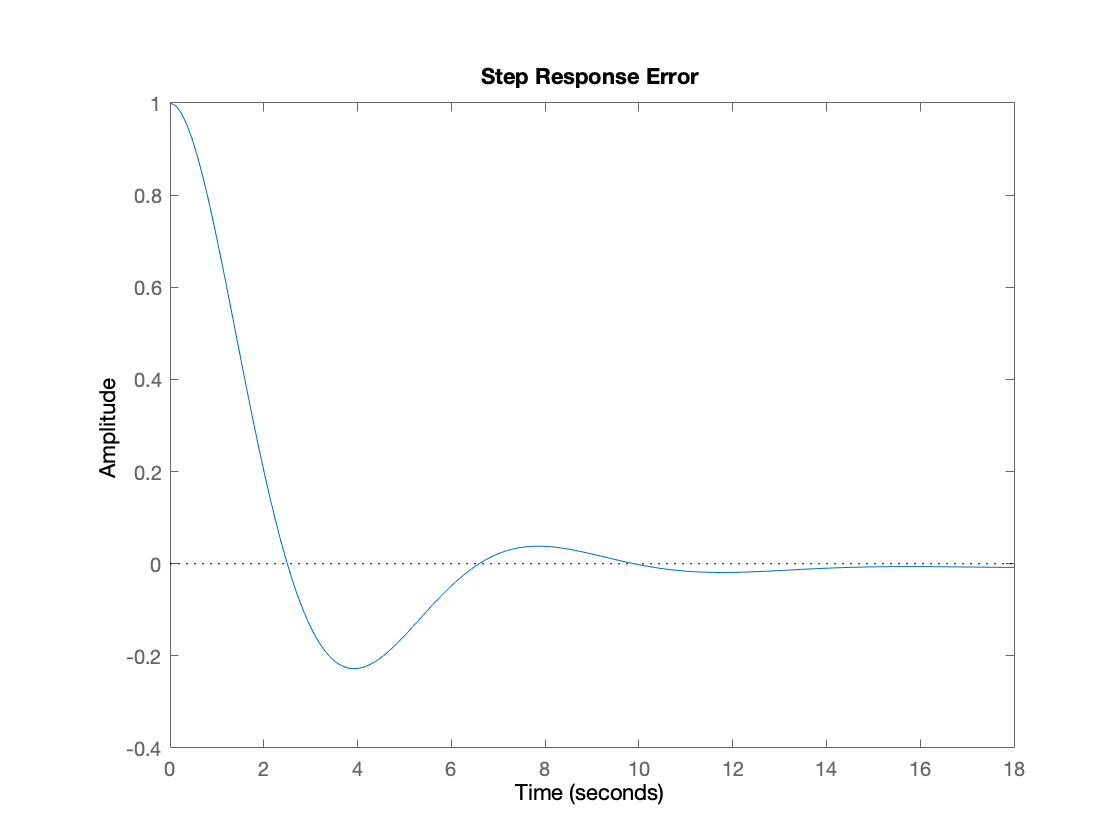


%% 2: MATLAB control toolbox
s = zpk('s');                       % define s in laplace domain
K = 0.8;
G_inner = feedback((s + 0.01)/s * K * 1/s,1);
G = (s + 0.01)/s * G_inner * 1/s;   % open loop transfer function
T = feedback(G,1);                  % closed loop transfer function 
T_e = 1 - T;                        % transfer function between input and error

step(T_e)
title('Step Response Error')

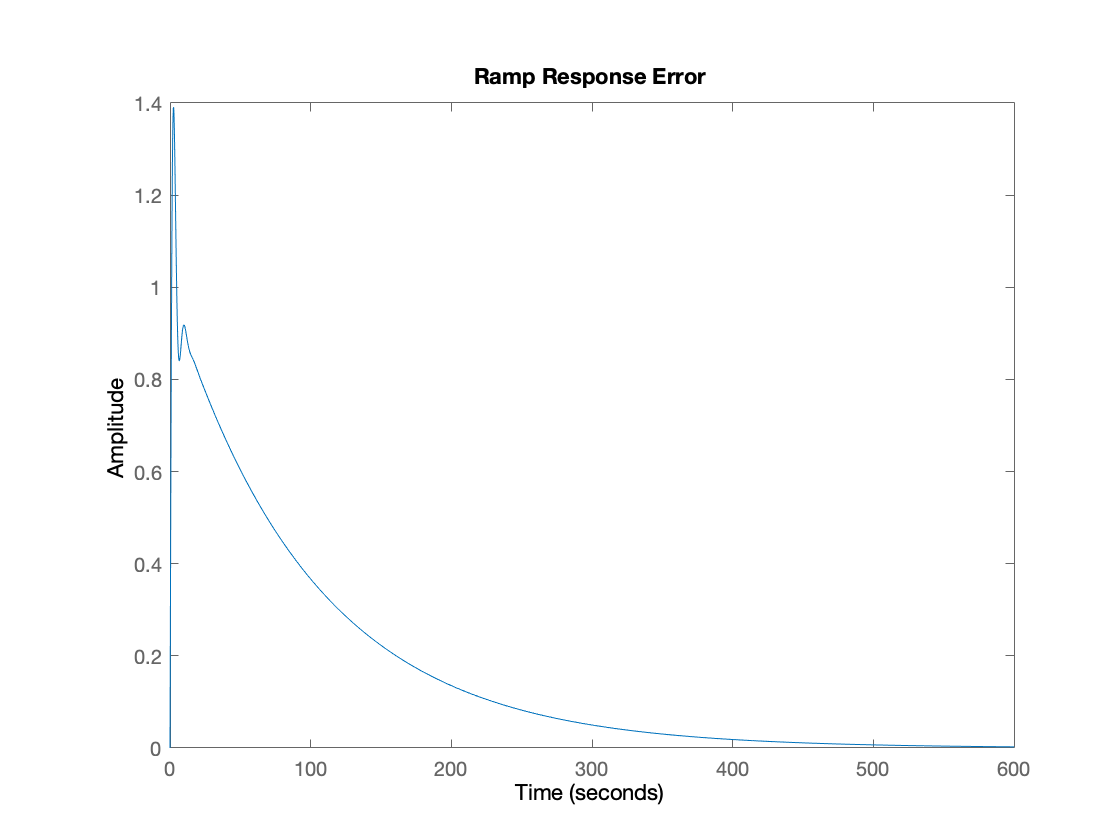


step(T_e * 1/s)                     % ramp = step * 1/s
title('Ramp Response Error')

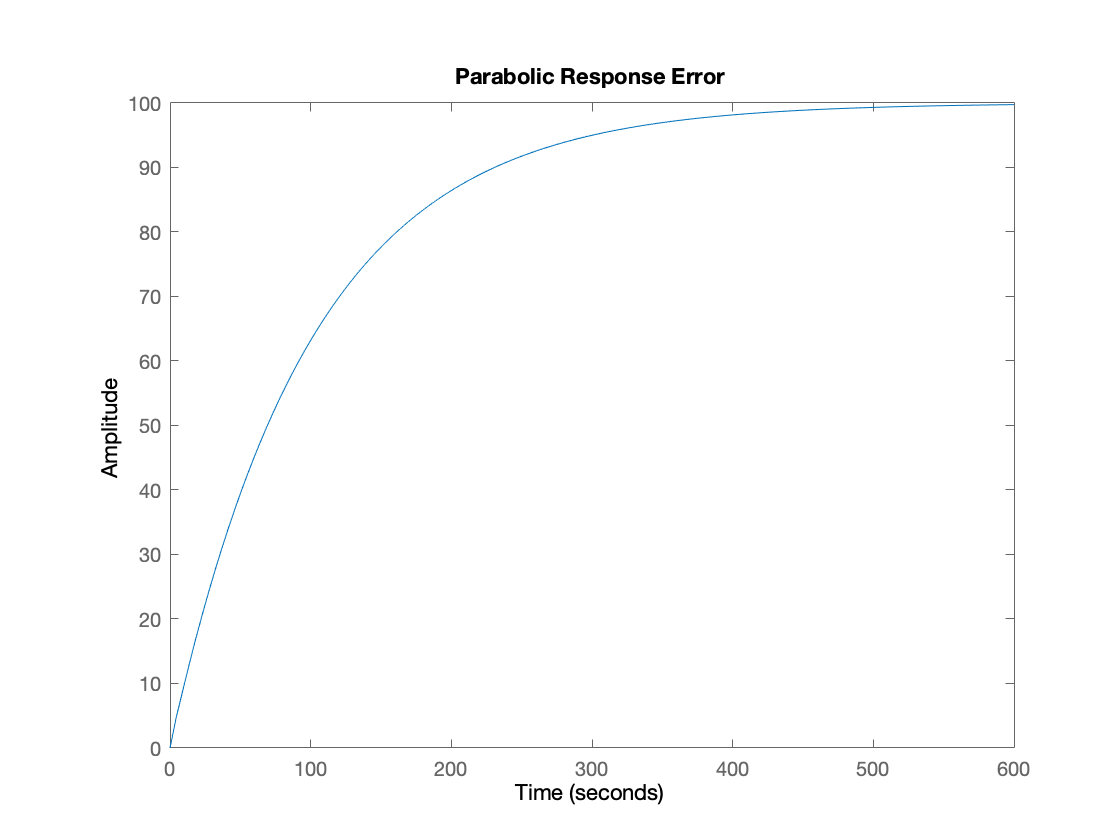


step(T_e * 1/s^2)                   % parabola = step * 1/s^2
title('Parabolic Response Error')

**Example 2.** A boat is circling a ship that is using a tracking radar. The speed of the boat is 20 knots, and it is circling the ship at a distance of 1 nautical mile, as shown below. Find the value of K so that the boat is kept in the cneter of the radar beam with no more than 0.1-degree error.

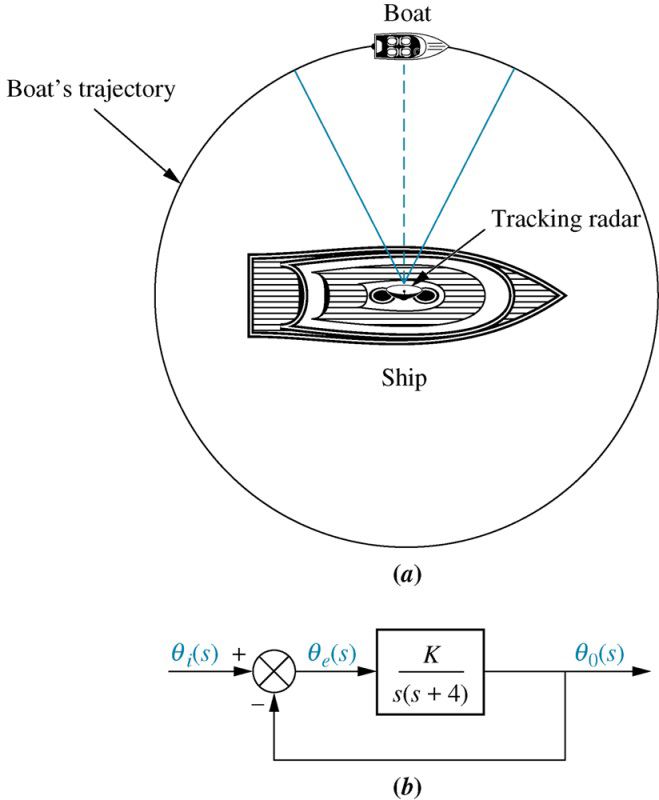

Angular velocity: $\omega=\frac{V}{r}=\frac{20}{1}\cdot\frac{\text{nm/hr}}{\text{nm}}=\frac{20}{3600}\cdot\frac{rad}{sec}=5.56\cdot10^{-3}(\text{rad/sec})$

For $0.1^{o}$error, $e_{ss}=0.1^o\cdot \frac{2\pi}{360^o}=0.0017 [\text{rad}]$, and $K_v=\lim_{s\rightarrow0}sG(s)=\lim_{s\rightarrow0}\frac{sK}{s(s+4)}=\frac{K}{4}$


$$\omega\cdot 1/K_V=e_{ss}$$


hence, $K=12.76$

ess_rad = 0.1 *2*pi/360             % error in radian

ess_rad = 0.0017

v = 20                              % 1 knot = 1 [nautical mile / hour]

v = 20

r = 1                               % radius  = 1 [nautical mile] 

r = 1

omega = v / r / 3600                % angular velocity [radian / second] 

omega = 0.0056


syms s K
G = K/(s*(s+4));
Kv = limit(s*G, s,0)

$$Kv = \frac{K}{4}$$


eqn = omega * 1/Kv == ess_rad

$$eqn = \frac{1}{45\,K}=\frac{\pi }{1800}$$


K = solve(eqn, K)

$$K = \frac{40}{\pi }$$

K = vpa(K,4)

$$K = 12.73$$

K = double(K)                      % symbolic K to double float K 

K = 12.7324


s = zpk('s');
G = K / (s*(s+4));
T = feedback(G,1)                  % closed loop transfer function 


T =
 
        12.732
  ------------------
  (s^2 + 4s + 12.73)
 
Continuous-time zero/pole/gain model.




T_e =
 
       s (s+4)
  ------------------
  (s^2 + 4s + 12.73)
 
Continuous-time zero/pole/gain model.



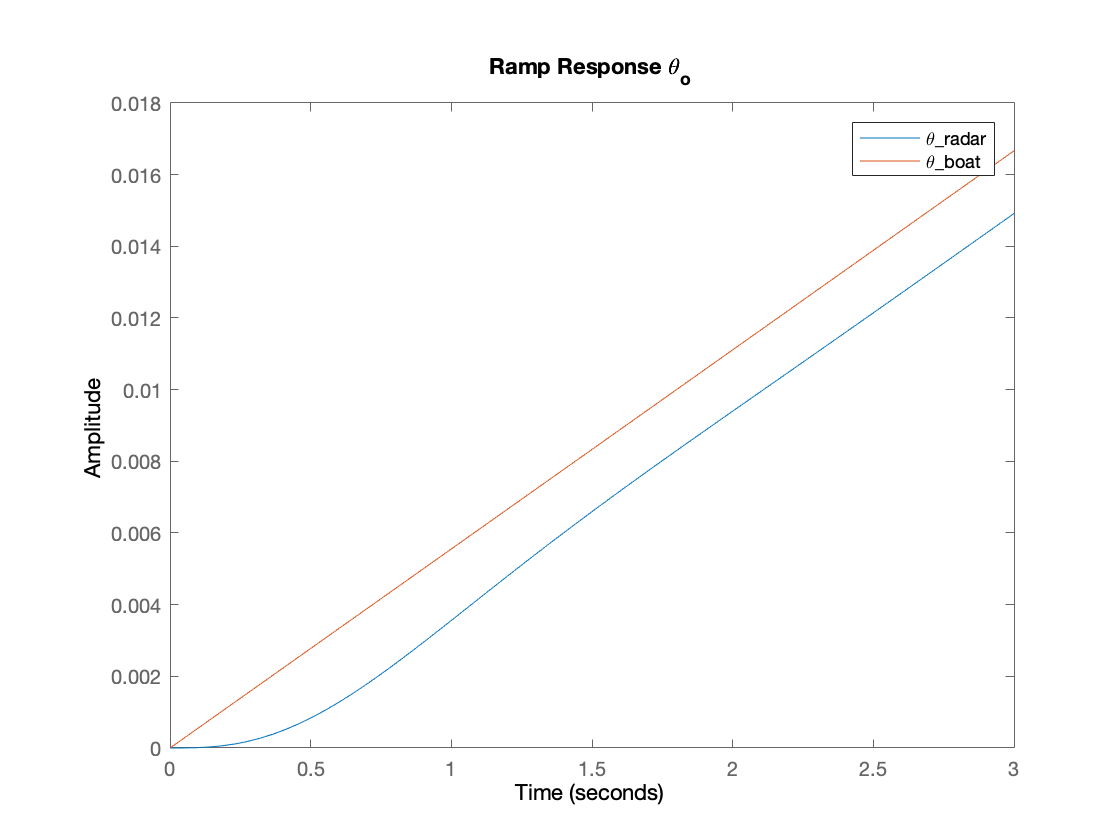

step(T * omega/s, omega/s)         % ramp response of \theta_o
title('Ramp Response \theta_o')
xlim([0, 3])
legend('\theta_{radar}','\theta_{boat}')

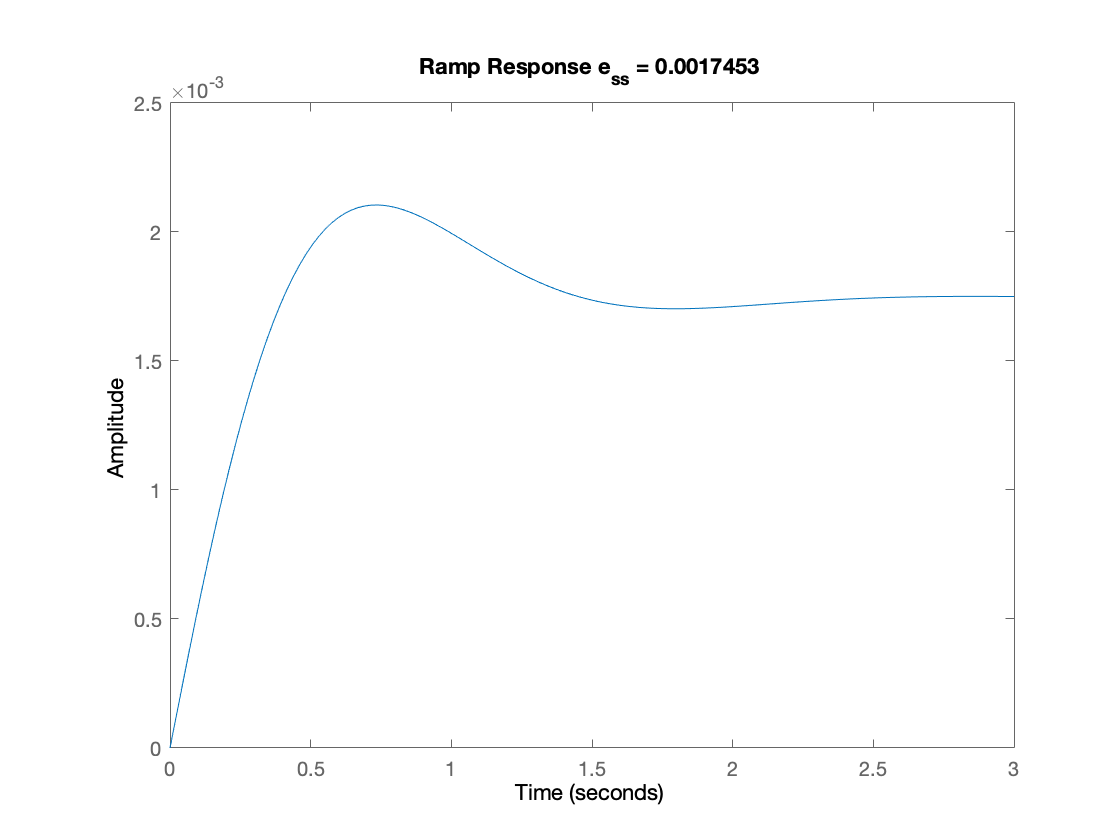


T_e = 1 - T                        % transfer function for error
step(T_e * omega/s)                % ramp response of error signal
title(['Ramp Response e_{ss} = ',num2str(ess_rad)])